# Simulation of General oscillators

In order to break down the important elements of spring-wing dynamics, we need a framework that enables us to quickly swap out and compare different versions of the model. In general,


$$I(t)\ddot{\theta}+f_d(\dot{\theta})+f_e(\theta) =u(\mathbf{\theta},t)$$


Where $I$ is the inertia of the system, which may be a function of time, $f_d$ is the drag function (aero, viscous, friction, structural, etc.), $f_e$ is the elasticity function (linear spring, hardening or softening spring, etc.), and $u$ is the force applied to the system, which may be a function of the state and/or time.

I'd like to write a function that allows us to specify each of those functions - $I$, $f_d$, $f_e$, $u$ - explicitly to maintain some consistency.

# The *sim_opts *struct

A struct used to feed in the different simulation options. The options that are currently available are:

## Inertia

- *constant - *Inertia does not change during operation. Takes one parameter (the inertia)

## Drag

- *aero - *Quadratic damping such that $F_d = \beta|\dot{\theta}|\dot{\theta}$. Takes one parameter (drag coefficient)

- *viscous - *Viscous damping such that $F_d = \beta\dot{\theta}$. Takes one parameter (viscous coefficient)

## Spring

- *linear - *Constant coefficient linear spring. Takes one parameter (spring stiffness). 

- *piecewise - *Nonlinear spring constructed as a cubic spline such that 


$$f_e(x) = \left\{
        \begin{array}{ll}
            K_1 & \quad |x| \leq d_{stop} \\
            K_2 & \quad |x| \gt d_{stop}
        \end{array}
    \right.

$$


When $K_2>K_1$ you have strain stiffening (below), but you can also have strain softening or a freeplay (i.e. gear backlash) zone.    

              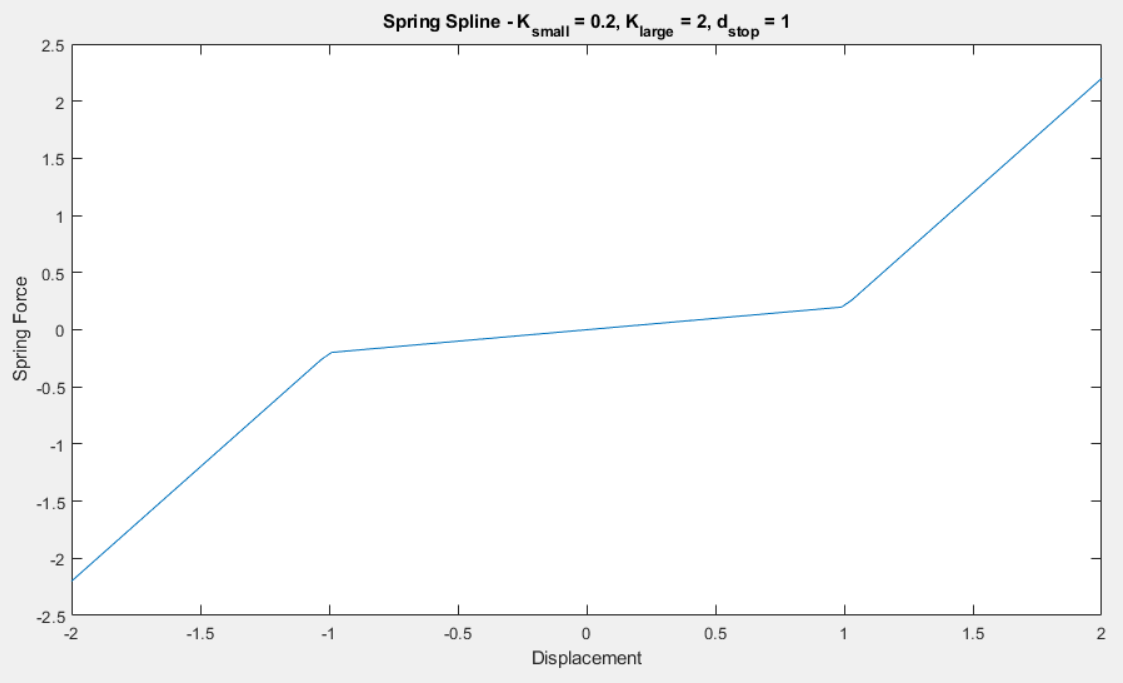

                Takes 3 parameters in a vector, [$K_1$, $K_2$, $d_{stop}$] 

- *pendulum - *This isn't quite a spring, but it is a rectifying function of the angle of the "wing". The "elasticity" is a function of the mass of the pendulum, $m$, gravity, $g$, the location of the center of mass, $r_{com}$, and the angle $\theta$:

 
$$f_e(x)= mg(r_{com}\sin\theta)$$


             Note that the inertia $I$ of the system now also changes with $m$ and $r_{com}$. Takes two parameters in a vector,  [$m$, $r_{com}$]

## Transmission

- *linear - *Constant coefficient between muscle/actuator length/displacement and wing angle. Takes one parameter (T)

## Force

- *par_sine - *Applies a sinusoidal torque input as in a parallel-elastic (indirect actuation) model. Takes two parameters in a vector, [Amplitude (Nm), Frequency (Hz)]

- *ser_sine - *Applies a sinusoidal displacement input as in a series-elastic (direct actuation) model. Takes two parameters in a vector, [Amplitude (radian), Frequency (Hz)]

- *dSA3 *- Asynchronous flapping based on the 3-parameter model of delayed stretch activation. Takes 3 parameters in a vector, [$r_3$, $\kappa = r_4/r_3$, $\mu$] 

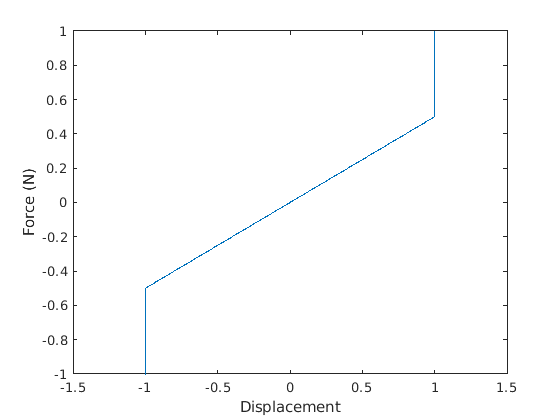

clear
% tic

sim_opts = struct();

sim_opts.inertiaMode    = 'constant';   % Constant inertia
sim_opts.params.inertia = 0.001;       % kg m^2

% sim_opts.dragMode       = 'aero';       % Aerodynamic Drag
% sim_opts.params.drag    = 0.002;        % drag coeff
sim_opts.dragMode       = 'viscous';       % Aerodynamic Drag
sim_opts.params.drag    = 0.02;        % drag coeff


% sim_opts.springMode     = 'linear';     % Linear spring
% sim_opts.params.spring  = 0.5;          % Nm/rad
sim_opts.springMode     = 'piecewise';  % Nonlinear spring
sim_opts.params.spring  = [0.5, 500, 1, 1]; % [soft spring, stiff spring, dStop, (optional) plotFlag]
% sim_opts.springMode     = 'pendulum';   % pendulum
% sim_opts.params.spring  = [0.001, 0.1]; % [pendulum mass (kg), CoM distance(m)]

sim_opts.transmissionMode = 'linear';   % Transmission
sim_opts.params.transmission = 1;       % Transmission ratio

% sim_opts.forceMode      = 'par_sine';   % Sinusoid in a parallel system
% sim_opts.params.force   = [1,2];        % [Amp, Freq]
sim_opts.forceMode      = 'dSA3';       % 3-parameter dSA
sim_opts.params.force   = [30,0.2,5];        % [r3, kappa, mu]

odefun = springWingFunSetup(sim_opts);

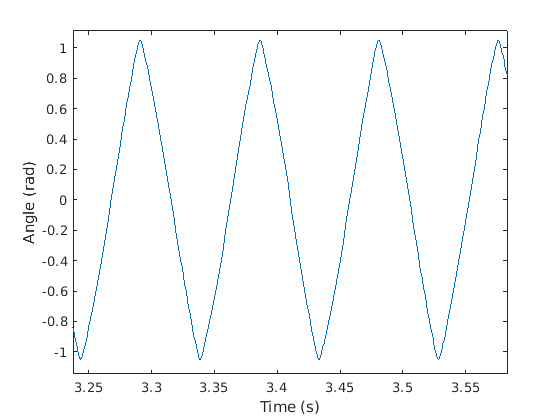

% toc
% Run!
if isequal(sim_opts.forceMode,'par_sine')
    [t,y] = ode45(odefun,[0,10],[0,0]);
    plot(t,y(:,1)) % plot angle
    xlabel("Time (s)")
    ylabel("Angle (rad)")
elseif isequal(sim_opts.forceMode,'dSA3')
    [t,y] = ode45(odefun,[0,10],[0,1,0,0]);
    plot(t,y(:,1)) % plot angle
    xlabel("Time (s)")
    ylabel("Angle (rad)")
end

%% Estimate frequency of oscillations TODO